## Exploration of Conjugate Gradient

    The convergence speed of the Conjugate Gradient method for solving linear least squares problem is quite fast. The convergence speed is at most $n$ iterations for a symmetric positive definite matrix $A$ of size $n\times n$. We decrease the necessary iterations by adding preconditioners. This is an exploration of how eigenvalues impact the convergence speed of this solver.


$$Ax=b$$


### For the 2x2 Case with spread out eigenvalues:

% Creating an exact solution
A2spread = diag([1,20]);
xexact2 = [2;3];
b2spread = A2spread*xexact2;

% Converting into a linear operator
op2spread = MatrixLinearOp(A2spread);

% Using the solver
[x2spread,info2spread] = solver_CGLS(op2spread,b2spread,Tolerance=1e-12,MaxIterations=3);
lambda2spread = eig(A2spread);
eigSpread2spread = std(log10(lambda2spread),1);

### For the 2x2 Case with clustered eigenvalues:

% Creating an exact solution
A2cluster = diag([2,3]);
xexact2 = [2;3];
b2cluster = A2cluster*xexact2;

% Converting into a linear operator
op2cluster = MatrixLinearOp(A2cluster);

% Using the solver
[x2cluster,info2cluster] = solver_CGLS(op2cluster,b2cluster,Tolerance=1e-12,MaxIterations=3);
lambda2cluster = eig(A2cluster);
eigSpread2cluster = std(log10(lambda2cluster),1);

### For the 5x5 case with spread out eigenvalues:

A5spread = diag([2,4,6,8,10]);
xexact5 = randi(100,[5 1]);
b5spread = A5spread*xexact5;

% Converting into a linear operator
op5spread = MatrixLinearOp(A5spread);

% Using the solver
[x5spread,info5spread] = solver_CGLS(op5spread,b5spread,Tolerance=1e-12,MaxIterations=6);
lambda5spread = eig(A5spread);
eigSpread5spread = std(log10(lambda5spread),1);

### For the 5x5 case with clustered eigenvalues:

A5cluster = diag([2,2,2,2,6]);
xexact5 = randi(100,[5 1]);
b5cluster = A5cluster*xexact5;

% Converting into a linear operator
op5cluster = MatrixLinearOp(A5cluster);

% Using the solver
[x5cluster,info5cluster] = solver_CGLS(op5cluster,b5cluster,Tolerance=1e-12,MaxIterations=6);
lambda5cluster = eig(A5cluster);
eigSpread5cluster = std(log10(lambda5cluster),1);

Plotting attempt:

allEigSpreads = [eigSpread5spread eigSpread5cluster];
allIterations = [info5spread.iterations info5cluster.iterations]

allIterations =      5     2


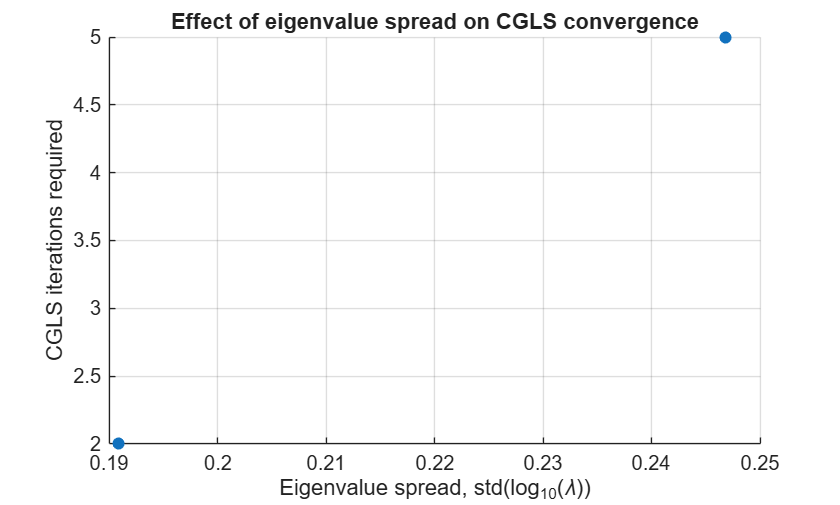

scatter(allEigSpreads,allIterations,'filled')

grid on
xlabel('Eigenvalue spread, std(log_{10}(\lambda))')
ylabel('CGLS iterations required')
title('Effect of eigenvalue spread on CGLS convergence')